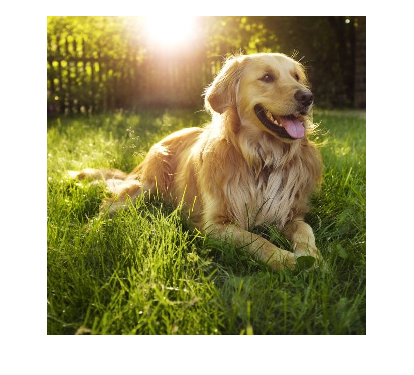

img = imread('squaredog.jpg');

imshow(img);

[IND,map] = rgb2ind(img, 32,'nodither');
img = uint8(ind2rgb(IND,map)*255);


BW = im2bw(img);
filled = imfill(BW, "holes");
eroded = imerode(double(filled),strel('disk',5));
dilated = imdilate(eroded, strel('disk',3));
BW = immultiply(dilated,BW);

CC = bwconncomp(BW,4);
L = labelmatrix(CC);
CP = label2rgb(L,'gray','k','shuffle');


BW = im2bw(255 - img);
filled = imfill(BW, "holes");
eroded = imerode(double(filled),strel('disk',5));
dilated = imdilate(eroded, strel('disk',3));
BW = immultiply(dilated,BW);

CC = bwconncomp(BW,4);
L = labelmatrix(CC);
CN = label2rgb(L,'gray','k','shuffle');

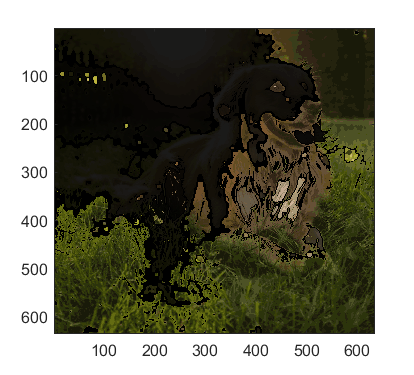



I = CP + CN;
outImg = double(img).*im2double(I);


imagesc(uint8(outImg));


%montage({img,outImg});

